## **Group Members**


p1 = {'givenName', 'surNAme', 'matriculationNumber'};
p2 = {'givenName', 'surNAme', 'matriculationNumber'};
p3 = {'givenName', 'surNAme', 'matriculationNumber'};
p4 = {'givenName', 'surNAme', 'matriculationNumber'};

Members = {'p1'; 'p2'; 'p3'; 'p4'};
GivenNames = {'Matsimbo Fotsing'; 'Tsiegoum Mouafo'; 'Dongmo Kingni Diffo'; 'Henschel'};
SurNames = {'Cecile Darelle'; 'Naomi Ghislaine'; 'Vianey'; 'Leuwaing Forsuh'};
MatriculationNumbers = {'3222693'; '3199972'; '3200261'; '3186914'};

groupTable = table(Members, GivenNames, SurNames, MatriculationNumbers);
disp(groupTable)

    Members          GivenNames                SurNames          MatriculationNumbers
    _______    _______________________    ___________________    ____________________

    {'p1'}     {'Matsimbo Fotsing'   }    {'Cecile Darelle' }        {'3222693'}     
    {'p2'}     {'Tsiegoum Mouafo'    }    {'Naomi Ghislaine'}        {'3199972'}     
    {'p3'}     {'Dongmo Kingni Diffo'}    {'Vianey'         }        {'3200261'}     
    {'p4'}     {'Henschel'           }    {'Leuwaing Forsuh'}        {'3186914'}     



# **Computer Based Engineering Mathematics**

#### `Lab Project`

#### **Project 2: It's all about the Primes**

#### *Introduction*

A prime number is a natural number greater than 1 that cannot be expressed as the product of two smaller natural numbers. In other words,* it has no divisors other than 1 and itself*. Natural numbers greater than 1 that are not prime are called *composite numbers*, as they can be written as the product of smaller natural numbers. A divisor of a number is any natural number that divides it exactly, leaving no remainder. Every natural number has at least two divisors, that is 1 and the number itself, but prime numbers have no other divisors besides these two.

# **Task 1**: RSA cryptosystem and prime numbers

## Prime Numbers & RSA Crytosystem

The **RSA** (**Rivest–Shamir–Adleman**) **cryptosystem** is a [public-key cryptosystem](https://en.wikipedia.org/wiki/Public-key_cryptography), one of the oldest widely used for secure data transmission that is, it enables secure digital communication without needing to share private keys in advance.. The [initialism](https://en.wikipedia.org/wiki/Initialism) "RSA" comes from the surnames of [Ron Rivest](https://en.wikipedia.org/wiki/Ron_Rivest), [Adi Shamir](https://en.wikipedia.org/wiki/Adi_Shamir) and [Leonard Adleman](https://en.wikipedia.org/wiki/Leonard_Adleman), who publicly described the algorithm in 1977.

#### **1) Why Prime Numbers Are Important?**

- A prime number is a number greater than 1 with only two divisors: 1 and itself.

- RSA starts by choosing **two large prime numbers**: p and q.

- Their product, n=p×q where n is **public**, p and q are **kept private** is called a **semiprime **[a number that is the product of **two prime numbers**]

- Factoring this product is **computationally hard**, providing RSA's security.

- **It helps in Preventing attacks** (by ensuring mathematical properties that can’t be mimicked with non-primes).

#### ** 2) How RSA Works?**

- Choose primes p and q. 

- Compute n = p x q, phi(n) = (p-1) (q-1) 

- Choose e such that gcd(e, phi(n)) = 1 

- Compute d where e x d equiv 1 (mod phi(n)) 

- Encryption: c = m^e mod n

- Decryption: m = c^d mod n

#### **3) Why It's Secure?**

- Based on the difficulty of factoring large semiprimes (e.g., n = p x q)

- No fast classical algorithms exist for factoring large numbers.

- Without knowing p and q, it’s extremely hard to find the private key

#### **4) Applications**

- Secure communication (emails, web traffic) 

- Digital signatures and authentication 

- HTTPS / TLS

# **Task 2**: Two prime number-related functions

a) Write your own MATLAB (or Octave) function to check if a number is a prime. Your function shall take a natural number as an input and return a boolean value to indicate if the input number is prime (return value true) or not (return value false).

#### ***LESS EFFICIENT CODE***

%% Task 2a alternative solution(less efficient)


function tf = IsPrimeNum(n)
% isPrimeNumber  Returns true if n is prime, false otherwise.
%
%   tf = isPrimeNumber(n) returns a logical 1 (true) if n is a prime
%   integer ≥ 2, and 0 (false) otherwise.

    % Handle n < 2
    if  n < 2
        tf = false;
        return;
    end
    % trial division up to n-1
    for k = 2:n-1
        if mod(n,k) == 0
            tf = false;
            return;
        end
    end

Is 999983 prime?: 1 
 Duration: 0.073 seconds


    % if no divisor found, it’s prime
    tf = true;
end
%test
tic;

Is 999983 prime using in_built isprime()?: 1 
 Duration: 0.092 seconds

isP2=IsPrimeNum(999983);
duration2=toc;
fprintf('Is 999983 prime?: %d \n Duration: %.3f seconds', isP2,duration2);

% unit test
tic;
isP2t=isprime(999983);
duration2t=toc;
fprintf('Is 999983 prime using in_built isprime()?: %d \n Duration: %.3f seconds', isP2t,duration2t);


#### ***MORE EFFICIENT CODE***

%Task 2a more efficient solution


function result = IsPrime(n)
% isPrimeNumber  Returns true if n is prime, false otherwise.
%
%   result = isPrimeNumber(n) returns a logical 1 (true) if n is a prime
%   integer ≥ 2, and 0 (false) otherwise.

    % Handle non-integers, n < 2, etc.
    if ~isscalar(n) || n ~= floor(n) || n < 2
        result = false;
        return;
    end

    % 2 is prime
    if n == 2
        result = true;
        return;
    end

    % eliminate even numbers > 2
    if mod(n,2) == 0
        result = false;
        return;
    end

    % trial division up to sqrt(n), checking only odd divisors
    r = floor(sqrt(n));
    for k = 3:2:r
        if mod(n,k) == 0
            result = false;
            return;
        end
    end

Is 999983 prime?: 1 
 Duration: 0.003 seconds


    % if no divisor found, it’s prime
    result = true;
end
%test
tic;

Is 999983 prime using in-built isprime()?: 1 
 Duration: 0.003 seconds

isP1=IsPrime(999983);
duration1=toc;
fprintf('Is 999983 prime?: %d \n Duration: %.3f seconds', isP1,duration1);

% unit test
tic;
isP1t=isprime(999983);
duration1t=toc;
fprintf('Is 999983 prime using in-built isprime()?: %d \n Duration: %.3f seconds', isP1t,duration1t);



b) Write a MATLAB(orOctave) function which takes a number n as an input parameter and returns a vector which contains the rst n prime numbers.

%% Task 2b
function [v]= firstNprimeNumbers(n)
    if n<1
        error('n must be a positive integer');
    end
    
    v= zeros(1,n);
    count=0;
    cand=2; %current candidate interger
    
    while count<n
        if IsPrime(cand)
        count=count+1;

     2     3     5     7    11    13    17    19    23



        v(count)=cand;
        end
      cand=cand+1;
    end
    
    end
% test
x=firstNprimeNumbers(9);
disp(x)


99th prime is: 523 


# **Task 3**:  List of prime numbers

Writing down a list of prime numbers (2, 3, 5, 7, 11, 13, 17, 19, 23, ...) we can see that the 9th prime is 23 and the sum of the prime numbers below 15 is 

                                                    2 +3+5+7+11+13=41.

3a) 

i) What is the 99th prime number?

%% Task 3a i

first99Primes=firstNprimeNumbers(99);
prime99=first99Primes(99);
fprintf('99th prime is: %d \n', prime99);

9999th prime is: 104723 


ii) And what is the 9999th prime number?

% Task 3a ii

first9999Primes=firstNprimeNumbers(9999);
prime9999=first9999Primes(9999);
fprintf('9999th prime is: %d \n', prime9999);


3b) Find the sum of all the prime numbers 

#### ***LESS EFFICIENT CODE***

%% Task 3b sum of all primes below n with unoptimised IsPrimeNum

function s = sumPrimesBelow(N)
    if N < 2   %avoid code crashing when n<1
        s = 0;
        return;
    end
    s = 0;
    for cand = 2 : N
        if IsPrimeNum(cand)
            s = s + cand;
        end
    end
end

sum of primes < 1500 is 165040


i) below 1500

%test i

m=1500;
tic;
sum1=sumPrimesBelow(m);
elapseda = toc;
fprintf('sum of primes < %.0f is %.0f\n',m,sum1);

ii) below 1.5 Million

%test ii

n=1.5e6;
tic;
sum2=sumPrimesBelow(n);
elapsedb= toc;
fprintf('sum of primes < %.0f is %.0f\n',n,sum2);

3b)   Find the sum of all the prime numbers 

#### ***MORE EFFICIENT CODE***

%% Task 3b sum of all primes below n with optimised IsPrime

function s = improvedSumPrimesBelow(N)
    if N < 2
        s = 0;
        return;
    end
    s = 0;
    for cand = 2 : N
        if IsPrime(cand)
            s = s + cand;
        end
    end
end


i) below 1500

%test i

sum of primes < 1500 is 165040


Elapsed time: 0.004 seconds


m=1500;
tic;
sum3=improvedSumPrimesBelow(m);
elapsedc = toc;
fprintf('sum of primes < %.0f is %.0f\n',m,sum3);
fprintf('Elapsed time: %.3f seconds\n', elapsedc);

ii) below 1.5 Million

%test ii

sum of primes < 1500000 is 82074443256


Elapsed time: 3.249 seconds


n=1.5e6;
tic;
sum4=improvedSumPrimesBelow(n);
elapsedd= toc;
fprintf('sum of primes < %.0f is %.0f\n',n,sum4);
fprintf('Elapsed time: %.3f seconds\n', elapsedd);

# **Task 4**: Prime number theorem

- Plot the prime-counting function π(x) which is de ned to be the number of primes less than or equal to x, for any real number x. For example, π(12) = 5 because there are ve prime numbers (2, 3, 5 7, and 11) less than or equal to 12. Choose a suitable axis scaling and label your graphics meaningfully.

%% Task 4.1


function p= pie(v)
    p=0;
    for i=2:v
        if(IsPrimeNum(i))
            p=p+1;
        end
    end
end
x=(10:10:100);
y=zeros(1,length(x));

     4     8    10    12    15    17    19    22    24    25



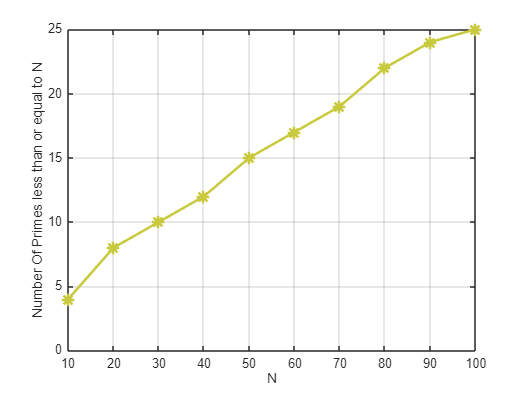

for i= 1:length(x)
       y(i)=pie(x(i)); 
end

disp(y)

p=plot(x,y);
%%title("Graph of prime-counting function pie(x)");
xlabel('N')
ylabel("Number Of Primes less than or equal to N")


p.LineWidth = 2;
p.Color = [200/255 201/255 60/255];
p.Marker = "*";
p.MarkerSize = 10; 
grid on;


2. The prime number theorem states that x ln x is a good approximation to π(x). Plot the ratio π(x)/ x ln x. Set the upper limit of x to visualize that this ratio approaches 1 for large x. Choose a logarithmic scaling for the x-axis.

#### ***LESS EFFICIENT CODE***

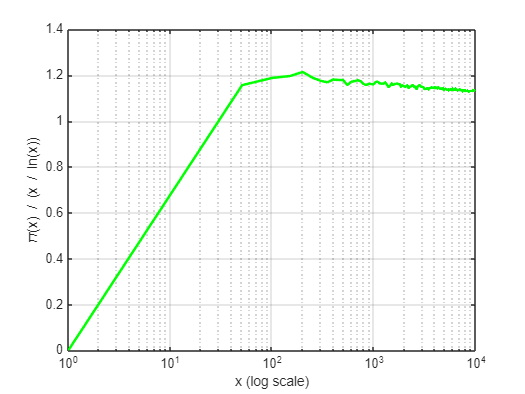

%% Task 4.2 simple


x_max = 1e4;

% claculating pie_x for some x values
tic;
x_values = 1:50:x_max;
pie_x=zeros(1,length(x_values));
for i= 1:length(x_values)
       pie_x(i)=pie(x_values(i)); 
end

% calculating x/lnx(approx_values) for these same x values

approx_values = x_values ./ log(x_values);

% calculating ratio (pie_x/approx_values) 

ratio = pie_x ./ approx_values;

%plotting


semilogx(x_values,ratio,'g-', 'LineWidth', 2)
xlabel('x (log scale)');

Plot Duration is: 5.477 seconds


ylabel('\pi(x) / (x / ln(x))');
grid on;
time1 = toc;
fprintf('Plot Duration is: %.3f seconds\n', time1)

#### ***MORE EFFICIENT CODE***

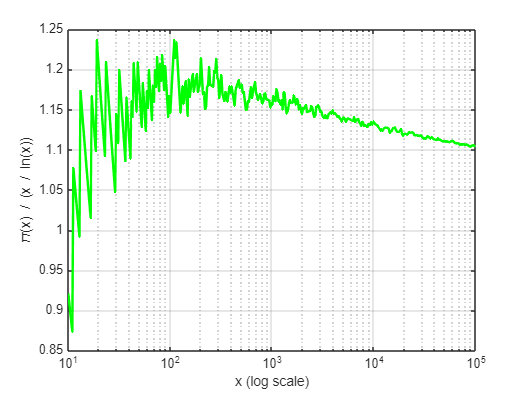

%% Task 4.2 with log space and inbuilt isprime() optimisation


x_max = 1e4;

% claculating pie_x for some x values
tic;
x_values = logspace(1,5,400);
pi_x=zeros(1,length(x_values));
for i= 1:length(x_values)
       pi_x(i) = length(primes(floor(x_values(i)))); 
end

% calculating x/lnx(approx_values) for these same x values

approx_values = x_values ./ log(x_values);

% calculating ratio (pie_x/approx_values) 

ratio = pi_x ./ approx_values;

%plotting


semilogx(x_values,ratio,'g-', 'LineWidth', 2)
xlabel('x (log scale)');

Plot Duration is: 0.173 seconds


ylabel('\pi(x) / (x / ln(x))');
grid on;
time1 = toc;
fprintf('Plot Duration is: %.3f seconds\n', time1)

# **Task 5**: Largest prime factor

The prime factors of 13195 are 5, 7, 13 and 29. Thus, the largest of them is 29.

%% Task 5 optimised

function prime_max = lazyLargestPrimeFactor(N)
    prime_max=0;
    for i= 2:floor(sqrt(N))
        while mod(N,i) == 0 && IsPrimeNum(i)
            prime_max = i;
            N = N / i;
        end
    end
    if N > 1 % because else p_max will correctly hold the largest prime factor found.
        prime_max = N;
    end
end

Largest Prime Factor of 2287946: 2797 


p1=lazyLargestPrimeFactor(2287946);                       %test 1

Largest Prime Factor of 565499313531: 8038027


p2=lazyLargestPrimeFactor(565499313531);                  %test 2
fprintf('Largest Prime Factor of 2287946: %d \n', p1);
fprintf('Largest Prime Factor of 565499313531: %d\n', p2);

# **References:**

- Rivest, R. et al. (1978). Communications of the ACM. [https://doi.org/10.1145/359340.359342](https://doi.org/10.1145/359340.359342)

- Stallings, W. (2016). Cryptography and Network Security.

- Wikipedia: RSA (cryptosystem

- Exploring RSA encryption: a comprehensive guide to how it works. https://www.comparitech.com/blog/information-security/rsa-encryption/